# Programmierblatt 2

#### Finite Differenzen, Laplace und Poisson Gleichung

Bearbeitende Studierende:

Jonathan Schnitzler    Matr. - Nr: 3465192

Matthias Gültig           Matr. - Nr: 3469020

Anmerkungen: Alle Aufgaben wurden bereits mit der freiwilligen aber sinnvollen Forderung nach Erweiterung bzw. Generalisierbarkeit implementiert

##  Aufgabe 1 (FD-Gitter)

In dieser Aufgabe wird das Gitter $\Omega =\left({\left(0,3\right)}^2 \backslash \left(\left\lbrack 2,3\right)\times \left(0,1\rbrack \right.\right)\right)\backslash \left(\left(0,1\right\rbrack \times \;\left\lbrack 2,3\right)\right)$

Die Grundlegende Idee ist die kleinstmögliche Basis $\Omega {\;}_R$ zu schaffen, sodass $\bar{\Omega {\;}_h \;} \subset \;\Omega {\;}_R$ und ein rechteckiges Würfelgitter ist. Dann reicht es aus diesem allgemeinen Gitter kleinere Rechtecke "auszuschneiden", und man kann jedes beliebige gewünschte Gebiet erhalten.

omeg.o = [0,0]

omeg = struct with fields:
    o: [0 0]
    x: 3
    y: 3
    h: 1


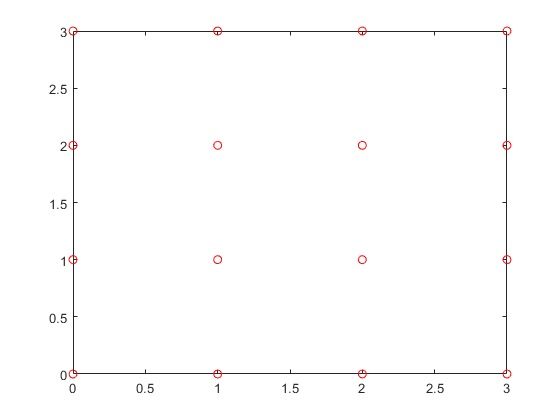

omeg.x = 3;
omeg.y = 3;
omeg.h = 1;

Omega = genRectMesh2D(omeg);
Omega = Omega.pointMat;
plot(Omega(:,1), Omega(:,2),'ro');

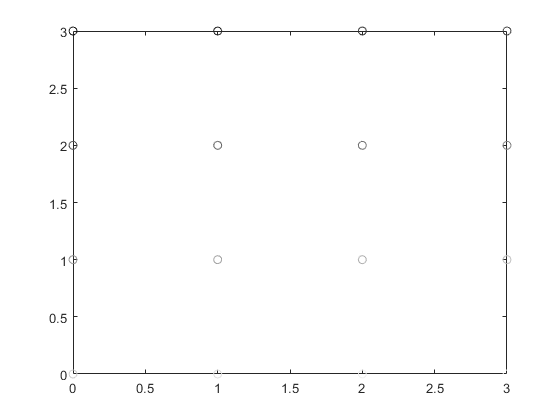




figure;
plot(omeg.o(1),omeg.o(2),'ro');
axis = [omeg.o(1),omeg.o(1)+omeg.x, omeg.o(2), omeg.o(2)+omeg.y];
hold on
nOmega = size(Omega,1);
for k=1:nOmega
    color = ones(3,1)*(k/nOmega);
    plot(Omega(k,1),Omega(k,2),'Color',color,"Marker",'o')
    
    drawnow
    pause(0.25)
end

function OmegaHBar = genRectMesh2D(omeg)
%Input is a struct specifying the origin the X-Length, the Y-Length and the
%Meshsize h
    if mod(omeg.x,omeg.h) ~= 0 || mod(omeg.y,omeg.h) ~= 0
        error("X-Length or Y-Length are not applicable with the Meshsize of h");
    end
    
    nX = omeg.x/omeg.h;
    nY = omeg.y/omeg.h;
    N = (nX+1).*(nY+1);
    OmegaHBar.omeg = omeg;
    OmegaHBar.pointMat = zeros(N,2);
    for kY = 0:nY
        for kX = 0:nX
            OmegaHBar.pointMat(kY*(nX+1) + (kX + 1),:) = [omeg.o(1) + kX *omeg.h, omeg.o(2) + omeg.y - kY * omeg.h];
        end
    end
end

function OmegaHBar = MeshSubtract(Omega, subOmega)
%Subtracts a rectangular mesh from an arbitrary cubic Mesh while keeping the
%edges
subOmega.omeg. = 


end

function findNeighbor